# **Week 7: Efficient programming**

This live script introduces good coding practices in Matlab for writing efficient code - that is code that doesn't crash nor it takes ages to run! 

The topics covered are:

- monitor performance

- vectorization - Matlab loves vectors!

- preallocation

- error handling

## **Monitor performance**

To improve performance, we need to first measure performance. One way to do so, is to measure the time it takes to run the code *before and after optimization*. 

**Q: how can we measure the time it takes to run our code? (seen this already in the Intro)**

% measure the elapsed time to run matrix multiplication of two (relatively
% big) matrices A and B

A = rand(2000, 50);
B = rand(1000, 50);


The computer's background tasks may affect a given timing measurement. You can perform multiple measurements by tracking the output of the toc() function

Use a for loop to perform 5 different measurements and estimate the average 'elapsed time' across measurements

## Vectorization

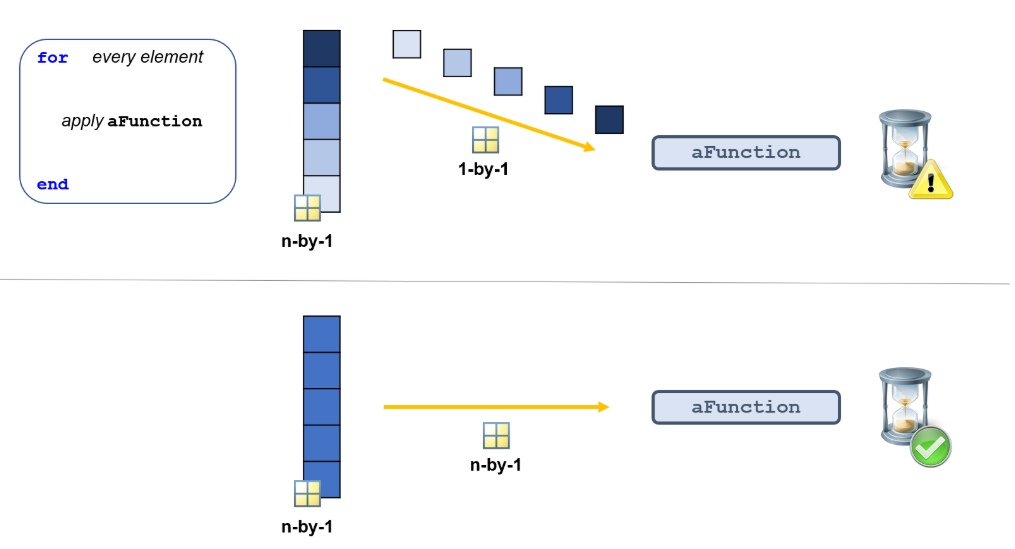

Matlab mainly uses vectorized functions and operations. 

One should try to vectorize their matlab code as much as possible.

Consider for example estimating the sum of 4,000 elements using a for loop versus Matlab's sum function

A = rand(1, 4000);

% use a for loop to estimate the sum of all elements of A

% use matlab's function sum()


** ****Matlab loves vectors!!******

Other examples of vectorization: **scalar (or vector) implicit expansion **-allows simple syntax-: Matlab will expand an array along the dimension of length 1 to make it match the size of the other array

**Consider the addition of a matrix with a scalar **

A = rand(3,2)
S = 2;
D = A + S

**Now consider the addition of 2 arrays/matrices, A and B**

Case 1. A and B are of equal size

A = rand(3,2);
B = rand(3,2);
C = A + B; 

Case 2. A is a matrix, but B is a vector with equal number of rows as A

% write code here

What if the length of the first dimension of B is not equal to the length of the first dimension of A?

% write code here

 Be careful of implicit expansion, you may end up with unexpected results, for example a matrix instead of a vector or scalar.

(Unwanted!) case 3. A is column vector (1x5) and B is a row vector (5x1). 

% write code here

## Preallocation

To keep array operations efficent, Matlab stores them in a contiguous block of memory. 

But what if you have a constantly growing array. like for instance an output variable in a for loop? Matlab may reserve memory space that is not enough for the final output.

 **Unless you *****preallocate*****, i.e. define an array from the start so that sufficient memory space is reserved. **

- How to preallocate *numeric arrrays*? 

1.Use array creation functions, such as zeros() or NaN().

xx = zeros(1,6000);
whos('xx') % by default xx is a double

yy = zeros(1, 5000, 'single');
whos('yy')

2.Assign a value to the last element of the array

% xx = 

### Practice

write code that takes two (big!) numbers M and N, and estimates all possible sums from 1:M and 1:N, resulting in a matrix with dimensions M x N. 

How long does it take to run without versus with preallocation?

Try different M and N's. Does the size matter?  

% code here
M = 3000;
N = 2000;


- **How to preallocate cell arrays and structure arrays? **

For non-numeric data types, such as cell arrays and structure arrays, you prellcoate the 'container' (eg. how many cells?) not the contents of each 'container'

- cell arrays

% define a cell array with 4 cells
C1 = cell(1,4);
% or
C2{1,4} = [];

Matlab creates the header for a 1x4 cell array, but does not allocate any memory for the contents of that cell array

### Practice

Populate a cell array C3, of size 4 x 5,  with matrices of random data. The matrix size increases by 10 based on its location in the cell array, sucn that the matrix in cell (1,1) is a 10x10 matrix, and the matrix in cell (4,5) is a 40 x 50 matrix. 

How long does it take for the code to run, with or without preallocation?

% write code here


- structure arrays

Again, can initialize the stucture to be the right size, without having to intialize the contents (these become automatically empty arrays).

% define a strucure array with 2 fields and 8 structures
S(8) = struct('Name', 'Mika', 'YearsAtPNI', 6);

Populate each field with a for loop

However there is a faster way!

C =  {'a', 'b', 'c', 'd', 'e', 'f', 'g'};
[S(1:7).Name] = C{:};

## Error handling

Let's assume you are writing code to model neural responses to the visual cues that appeared on the right hand side. 

As a first step, you want, on each trial, to bin the position of the cues  into bins of length 40 cm in the interval [0 200cm] (that's the length of the 'cue region'). That way you end up with a 'stimulus matrix', called 'binnedCues_r', with rows the number of bins and columns the number of trials

% let's pull out from the structure array the position of all cues (name of field: cue_pos_right)
%Cues_r = 

BinEdges = 0:40:200;
nBins = 200/40;

% preallocate!
%binnedCues_r = 
for iTr = 1:numel(Cues_r)
   whichBins_r = discretize(Cues_r{iTr}, BinEdges);
   for iB = 1:nBins
       binnedCues_r(iB,iTr) = sum(whichBins_r == iB);
   end 
end

One way to get around this is to skip the trials with empty arrays. You can do so using a try block inside the first for loop.

What is the matlab warning, if you just use a try block?

Add a catch block after the try block, and use the disp() to display the message 'empty array for trial [the number of that trial]'

% write code here

Or save the number of the 'problematic' trials into an array called trialsWithNoCues 

You can also add a variable name after the catch block. This variable is of a special data type called an *MException object* that contains information about the error that occurred

**Custom Warnings and Errors**

warning(): does not stop execution

error(): stops execution 

% in the piece of code above, substitute the disp() with either error() or
% catch()

### **Using the if continue statements**

An alternative to try catch blocks, *provided you know what the problem is*

Write code that tells matlab to skip a given trial, j,  if Cues_r{j} is an empty array